# Clase especial - UI

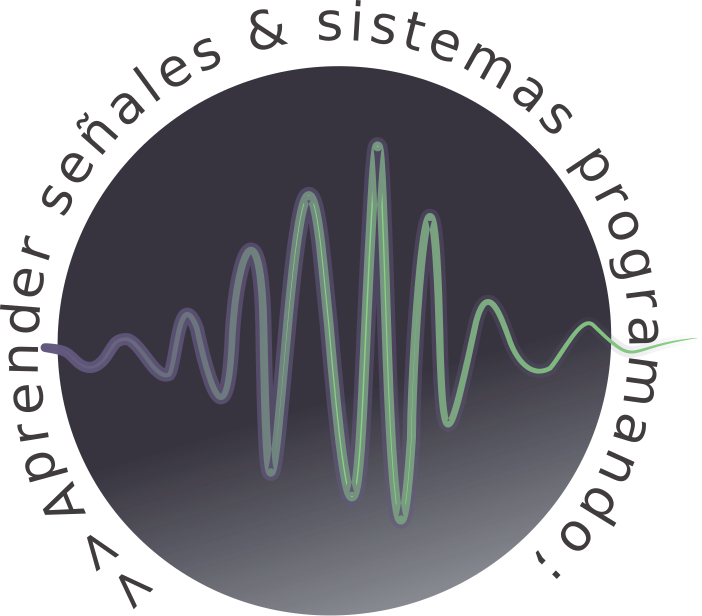

# Temario

- Introducción.

- Interface simple.

- Estructura del código.

- Escritura de *Callbacks.*

# Introducción

La interfaz gráfica de usuario, conocida también como GUI (del inglés graphical user interface), es un programa que actúa de interfaz de usuario, utilizando un conjunto de imágenes y objetos gráficos, llamados *componentes,* para representar la información y acciones disponibles en la interfaz*.* Su principal uso, consiste en proporcionar un entorno visual sencillo para permitir la comunicación con el sistema. 

Los componentes de una interface de usuario pueden estar comprendidos en menús, barras de herramientas, botones, listas y controles deslizantes, por nombrar algunos. Las creadas por Matlab pueden llevar a cabo cualquier tipo de procesamiento de cómputos, leer y escribir archivos,  comunicarse con otras interfaces y presentar tablas y/o gráficos. 

La siguiente figura ilustra una simple interface de usuario creada en Matlab.

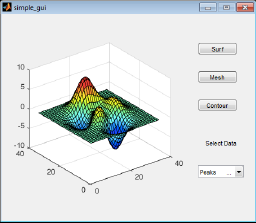

La misma contiene:

- Un componente de ejes.

- Un menú pop-up.

- Texto estático.

- Botones.

MATLAB permite desarrollar front-ends GUI que automatizan una tarea o cálculo. La GUI normalmente contiene controles tales como menús, barras de herramientas, botones y controles deslizantes. Muchos productos de MATLAB, como Curve Fitting Toolbox ™, Signal Processing Toolbox ™ y Control System Toolbox ™ incluyen aplicaciones con interfaces de usuario personalizadas. 

MATLAB permite tres caminos para la programación de GUI:

- GUIDE (Asistente).

- Programando (UIControls).

- App Designer.

## ¿Cómo trabajan las GUI?

Las interfaces esperan que el usuario manipule un control y responden a su acción de a turnos. Los controles y la UI misma tienen uno o más *callbacks *que se encargan de "llamar" a Matlab para llevar a cabo cierta tarea. Una acción particular del usuario, como podría ser el click de un botón, desencadanea la ejecución de un callback. Por lo tanto, el creador de GUI's debe encargarse de escribir callbacks que definirán qué es lo que producen los diferentes componentes de una interface de usuario. 

# GUIDE (Asistente)

GUIDE es un entorno de arrastrar y soltar (drag-and-drop) para establecer GUI. Las aplicaciones creadas con GUIDE pueden mostrar cualquier tipo de gráfico MATLAB, ademas proporciona varios componentes interactivos, incluyendo menús, barras de herramientas y tablas. Utilice este enfoque para crear aplicaciones sencillas que puedan mostrar cualquier tipo de gráfico. Sus principales ventajas son la facilidad y rapidez en el desarrollo, pero a expensas de la generación de codigo estructura por defecto muy extenso.

Para trabajar con este asistente es recomendable seguir los siguientes pasos:

- Abrir el entrono de trabajo `Blank GUI (Default)`.

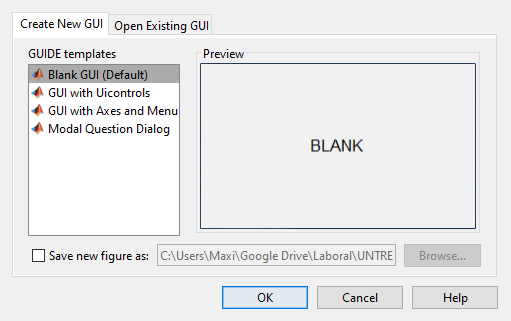

guide

- Configurar el entorno de trabajo.

`File > Preferences > GUIDE `

Clic en `Show names in component palette.`

`View > Object Browser`

Habilitanda ésta opción se pueden tener control de todos los objetos agregados.

Veamos un ejemplo creado a partir de este asistente

edit ejemplo_1.m

# Programando (UIControls)

El siguiente ejemplo ilustra cómo programar una GUI muy sencilla en Matlab. Los tópicos que se ven a continuación lo guiarán a través del proceso de creación de una interfaz de usuario. 

Primero debe crearse una función y la misma debe ser guardada en la carpeta de trabajo correspondiente. 

## Crear figura

El primer paso luego de creado el archivo .m de función consta de crear una figura con las siguientes líneas de código:

f = figure('Visible','off','Position',[360 200 450 285]);

A la figura se le establece una posición correspondiente y se la declara invisible mientras es construida. 

La propiedad *'Visible'* establece que el usuario pueda o no ver a la figura. En este ejemplo, la figura se hará visible para el usuario una vez que todos los componentes de la interfaz hayan sido inicializados. 

La propiedad *'Position' *un vector fila de cuatro elementos. Cada uno de ellos establece una posición de localización de la figura en cuestión. El primer elemento hace referencia a la distancia desde la izquierda, el segundo a la distancia desde abajo, el tercero al ancho de la figura y el cuarto a su largo. 

## Agregar componentes (uicontrols)

- Se crean los siguientes botones:

hsurf = uicontrol('Style', 'pushbutton',...
    'String','Surf','Position',[315 220 70 25]);
hmesh = uicontrol('Style', 'pushbutton',...
    'String','Mesh','Position',[315 180 70 25]);
hcontour = uicontrol('Style', 'pushbutton',...
    'String','Contour','Position',[315 135 70 25]);

Cada una de las declaraciones utiliza una serie de pares propiedad-valor del objeto **uicontrol **para definir a cada uno de los botones. 

- *Style* establece el tipo de componente, en este caso un botón. 

- *String* especifica el texto que aparece en el botón. 

- *Position* establece la posición del botón en la figura y sus dimensiones. 

Cada uicontrol es utilizado con un *handle *del botón creado. 

- Se crea el menú pop-up junto con su texto estático:

htext = uicontrol('Style', 'text',...
    'String','Select Data','Position',[325 90 60 15]);
hpopup = uicontrol('Style', 'popupmenu',...
    'String',{'Peaks','Membrane','Sinc'},'Position',[300 50 100 25]);

Al componente de menú pop-up en su propiedad *String *se le establece un valor de cell array de tres elementos, cada uno especificando los distintos items del menú. 

- Agregar ejes para gráfica.

ha = axes('Units','pixels','Position',[50, 60, 200, 185]);

Se establece que las unidades del objeto sean en pixels para que todos los componentes tengan las mismas. 

Por último, se declara visible a la figura:

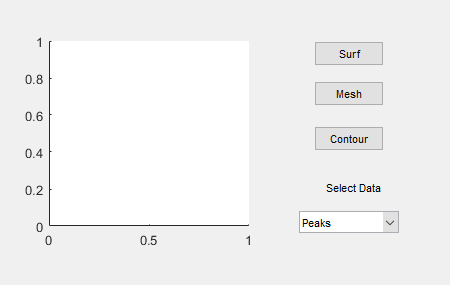

f.Visible = 'on';

## Programar el comportamiento de la GUI

- Progamar el menú pop-up.

El menú proporciona al usuario los datos que se desean graficar. Cuando el mismo selecciona un item del menú, a la propiedad *Value* del componente del menú se le asigna el valor del índice del cell array de la propiedad *String* que se corresponde con el item seleccionado. 

La función local *popup_menu_Callback ***se coloca justo después del código que se encarga de inicializar** los componentes de la UI.

Recupera los valores de *String* y de *Value *del componente menú pop-up y según el item que esté seleccionado se utilizan los datos correspondientes. 

% edit popup_menu_Callback
% Nota: descomentar el comando anterior para ver los comandos de código de la función local en cuestión.

- Progamar los botones.

Cada uno de los botones crea una gráfica distinta usando los datos correspondientes a cada item del menú. Plotean los datos almacenados en *current_data*. 

La funciones locales surfbutton_Callback*, meshbutton_Callback *y  **se coloca justo después del código que se encarga de inicializar** los componentes de la GUI.

% edit surfbutton_Callback
% edit meshbutton_Callback
% edit contourbutton_Callback

- Programar los *Callbacks*

Cada componente *uicontrol *tiene una propiedad *callback *asociada. Hay que especificar el nombre de la misma con el evento asociado. Se hace de la siguiente manera para este ejemplo:

Para el botón que define la gráfica tipo *Surf, *el control *uicontrol *queda establecido de la siguiente manera (no ejecutar esta fracción de código)

hsurf = uicontrol('Style', 'pushbutton',...
    'String','Surf','Position',[315 220 70 25],...
    'Callback',{@surfbutton_Callback});

Se ha añadido el valor de la propiedad *callback* del botón *uicontrol* cuyo *handle* es hsurf. *Callback* es el nombre de la propiedad y *surfbutton_Callback *es la función que se llama para ejectuar una acción cuando se utiliza ese componente. 

Se trabaja de manera análoga con los demás botones y el menú:

hmesh = uicontrol('Style', 'pushbutton',...
    'String','Mesh','Position',[315 180 70 25],...
    'Callback',{@meshbutton_Callback});
hcontour = uicontrol('Style', 'pushbutton',...
    'String','Contour','Position',[315 135 70 25],...
    'Callback',{@contourbutton_Callback});
hpopup = uicontrol('Style', 'popupmenu',...
    'String',{'Peaks','Membrane','Sinc'},'Position',[300 50 100 25],...
    'Callback',{@popup_menu_Callback});

- Inicialiar UI

Resta inicializar la interface. En primera instancia, las unidades de cada componente es conveniente que estén normalizadas, de esa manera la interface se comportará de manera  correcta cada vez que los ejes se redimensionen.

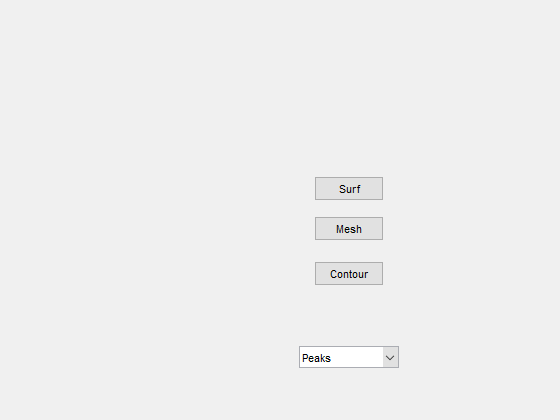

f.Units = 'normalized';
hsurf.Units = 'normalized';
hmesh.Units = 'normalized';

hcontour.Units = 'normalized';
htext.Units = 'normalized';
hpopup.Units = 'normalized';

Invalid or deleted object.


ha.Units = 'normalized';

Luego, se generan los datos para la graficación. 

peaks_data = peaks(35);
membrane_data = membrane;
[x,y] = meshgrid(-8:.5:8);
r = sqrt(x.^2+y.^2) + eps;
sinc_data = sin(r)./r;

Se plotean los datos del primer ítem del menú, para que cuando se ejecute el programa sea la información por defecto que esté graficada. 

current_data = peaks_data;
surf(current_data)

Por último, se establece un nombre para la figura, se la centra en pantalla y se establece positiva su visualización:

f.Name = 'GUI Simple';
movegui(f,'center');
f.MenuBar = 'none';
f.NumberTitle = 'off';
f.Visible = 'on';   

Listo! La UI está finalizada y lista para ser utilizada. 

Para ver el código completo:

% edit gui_simple

Para probar el programa, ejecutar el siguiente comando:

gui_simple

Podriamos agrupar todo en un solo archivo .m, por ejemplo:

edit ejemplo_2.m

# Estructura del código

## Organización del archivo

De manera general, un archivo de código de una GUI está compuesto por las secciones que se comentan a continuación. Es una buena práctica el de dividir las mismas con comentarios que ayuden al fácil reconocimiento de las mismas. 

1) Comentarios que contribuyan al material de ayuda de Matlab.

2) Tareas de inicialización, creación de datos y cualquier tipo de procesamiento que sea necesario para la construcción de componentes. 

3) Creación de figura y de sus componentes.

4) Inicialización de tareas que requieren de la existencia de los componentes anteriormente creados.

5) Callbacks para los componentes.

6) Funciones de utilidad.

## Plantilla

Esta es una plantilla que puede usarse para la creación de UI's.

% edit miui

## Creación de figuras

Las interfaces de usuario son figuras. Lo primero que se hace es crear una figura, antes de crear cualquier tipo de componente, y asignarle un handle a la misma.

fh = figure('Visible','on') % fh es el handle de la figura. 

Las propiedades más comunes de una figura son:

- MenuBar (valores: 'figure'/'none')

- Name (valores: String)

- NumberTitle (valores: 'on'/'off')

- Position (vector de 4 elementos [dist. izq., dist. abajo, ancho, largo])

- Resize (valores: 'on'/'off')

- Toolbar (valores: 'auto'/'none'/'figure')

- Units ('pixels'/'centimeters'/'characters'/'inches'/'normalized'/'points')

- Visible (valores: 'on'/'off')

fh.MenuBar = 'none';
fh.Name = 'Figura de prueba';
fh.NumberTitle = 'off';
fh.Resize = 'off';

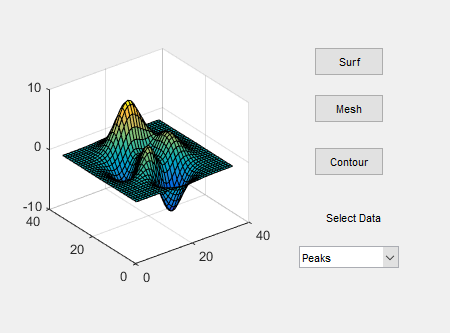

fh

## Componentes disponibles

Los controles de una interface de usuario son componentes UI; pueden ser botones, check boxes y controles deslizantes, entre otros; tablas que presenten datos en filas y columnas; paneles que agrupen elementos relacionados.

## Push button

El siguiente código crea un botón:

f = figure;
pb = uicontrol(f,'Style','pushbutton','String','Botón 1',...
    'Position',[50 20 60 40]);

El primer argumento de uicontrol especifica el partenesco; o sea, a qué estructura pertenece el botón. En este caso, es una figura pero podría ser cualquier otro contenedor como sea un panel o un grupo de botones. Con *'Style','pushbutton' *se establece que el componente es un botón.

## **Radio button**

El siguiente código crea un radio button:

f = figure;

fh =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


r = uicontrol(f, 'Style', 'radiobutton', ...
    'String', 'Radio button 1', 'Position', [30 20 150 20]);

## Toggle button

El siguiente código crea un toggle button, el mismo es un botón que elige entre dos posibles modos o estados:

f = figure;
tb = uicontrol(f, 'Style', 'togglebutton',...
    'String', 'L/R', 'Position', [30 20 100 30]);

## Check Box

El siguiente código crea un check box:

f = figure;
cb = uicontrol(f, 'Style', 'checkbox', ...
    'String', 'Check box 1', ...

fh =   Figure (5: Figura de prueba) with properties:

      Number: 5
        Name: 'Figura de prueba'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


    'Value',1,'Position', [30 20 130 20]);

La propiedad *Value *indica si el check box está o no tildado por defecto. Si el valor es 0, la caja aparece destilada mientras que si el valor es 1, ocurre lo contrario. 

## Slider

El siguiente código crea un control deslizante:

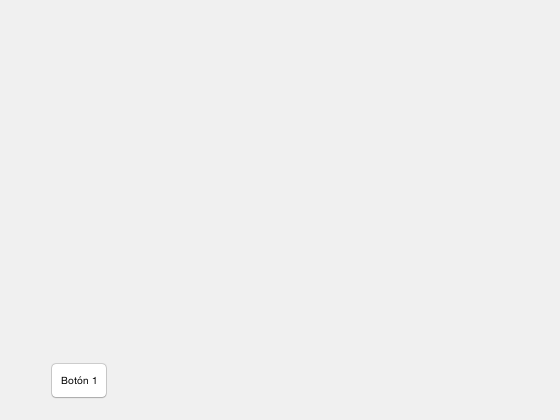

f = figure;
s = uicontrol(f, 'Style', 'slider',...
    'Min', 0, 'Max', 100, 'Value', 25, ...

    'SliderStep', [0.05 0.2], ...
    'Position', [30 20 150 30]);

*Min *y *Max *especifican el rango de valores entre los que toma el control deslizante. El primer valor debe ser más chico que el primero. *Value *especifica el valor por defecto en el que está establecido el control deslizante una vez que se ejecuta la UI. 

*SliderStep *es un array de dos elementos. El primero especifica la cantidad fraccional que se desliza el control cada vez que se haga click sobre alguna de las flechas laterales (en este caso, es del 5 por ciento). El segundo especifica la cantidad fraccional que se desliza el control cuando se hace click sobre el canal (en este caso, es del 20 por ciento).

## Texto estático

El siguiente código crea un texto estático:

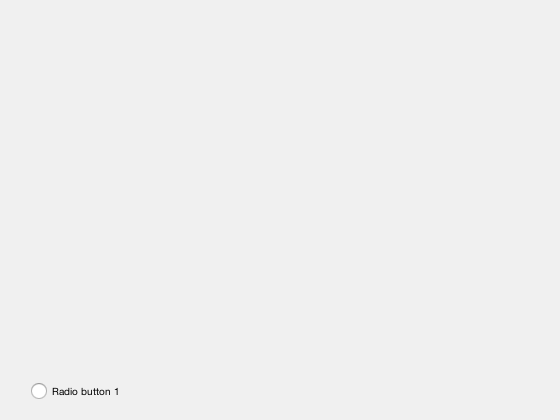

f = figure;
t = uicontrol(f, 'Style', 'text', ...
    'String', 'Texto estático', ...

    'Position', [30 50 150 30]);

## Editable text field

El siguiente código crea un campo de texto editable por el usuario:

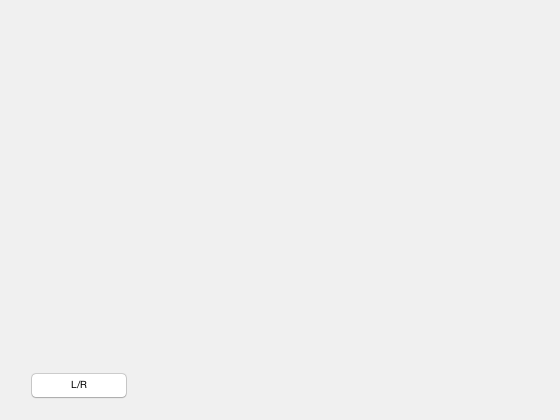

f = figure;
txtbox = uicontrol(f, 'Style', 'edit',...
    'String', 'Ingrese su mensaje', ...

    'Position', [30 50 130 20]);

Para permitir que haya múltiples líneas de texto el valor de *Max - Min* tiene que ser mayor  a 1. Si es menor o igual a 1, Matlab sólo muestra parte del texto escrito cuando el mismo supera las dimensiones del campo donde se encuentra el texto. 

## Pop-up menu

El siguiente código crea un menú pop-up.

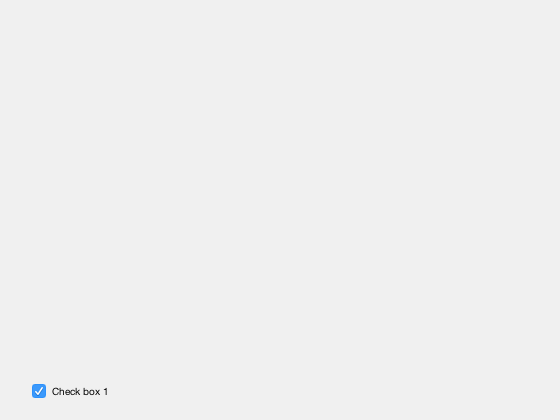

f = figure;
pm = uicontrol(f, 'Style', 'popupmenu',...
    'String', {'uno', 'dos', 'tres', 'cuatro'},...
    'Value', 2, 'Position', [30 80 130 20]);

En este caso, la propiedad *String* tiene como valor a un cell array cuyos elementos son strings que se corresponden con los diferentes ítems del menú. El valor de la propiedad *Value* indica cuál de los elementos se muestra por defecto. 

**List Box**

El siguiente código crea una lista:

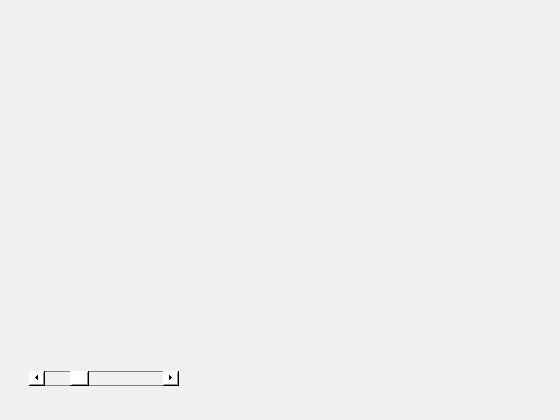

f = figure;
lb = uicontrol(f, 'Style', 'listbox',...
    'String', {'uno', 'dos', 'tres', 'cuatro'},...
    'Position', [30 20 180 80], 'Max', 2, 'Min', 0,'Value', [1 3]);

Para que el usuario pueda seleccionar más de un elemento. Max - Min debe ser mayor que 1. Estableciendo un vector como valor de la propiedad *Value*, se seleccionan por defecto los elementos indicados. Si se quiere que no haya una selección inicial, el valor de la propiedad *Value* debe ser una matriz vacía [ ]. 

**Tables**

El siguiente código crea una tabla a partir de los datos obtenidos a partir de la función `magic(5)`. 

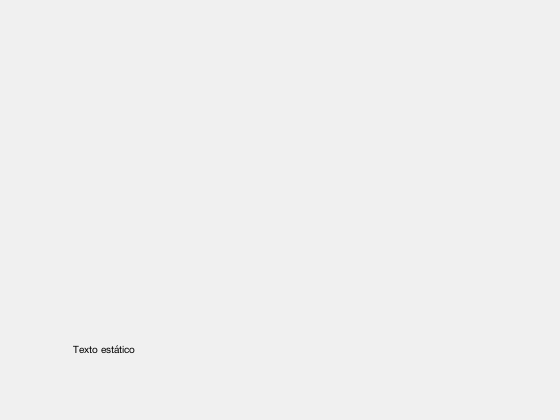

f = figure;
tb = uitable(f, 'Data', magic(5));

Pueden ser ajustados el ancho y el largo de la tabla para acomodar la extensión de los datos contenidos en la misma. La propiedad* Position* controla los límites externos de la tabla mientras que la propiedad *Extent *indica la extensión de los datos.

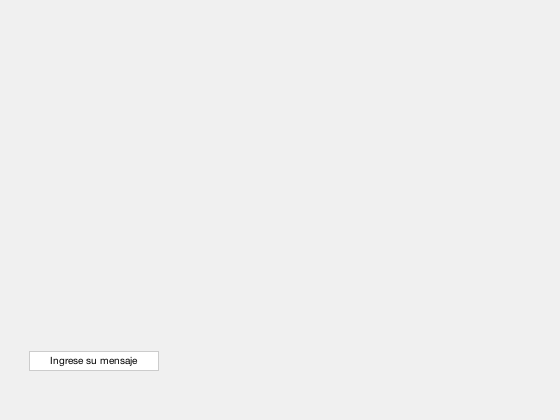

tb.Position(3) = tb.Extent(3);
tb.Position(4) = tb.Extent(4);

Pueden cambiarse otras alternativas:

- Para que el usuario pueda editar las celdas se trabaja con la propiedad *ColumnEditable*.

- Para especificar los nombres de las filas y de las columnas se trabaja con las propiedades *RowName* y *ColumnName.*

- Para especificar el formato de los datos contenidos se trabaja con la propiedad *ColumnFormat*.

**Panels**

El siguiente código crea un panel. 

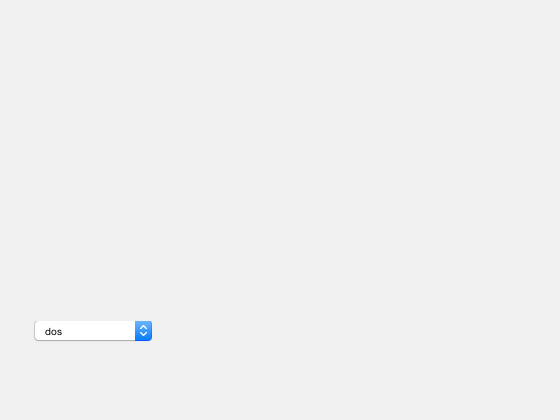

f = figure;
p = uipanel(f, 'Title', 'Mi panel', ...
    'Position', [.25 .1 .5 .8]);

El vector que es el valor de la propiedad *Position *especifica la localización y el tamaño del panel como fracción del contenedor. Si la figura se redimensiona, ocurre lo mismo de manera proporcional con el panel. 

Los siguientes comandos agregan dos botones al panel:

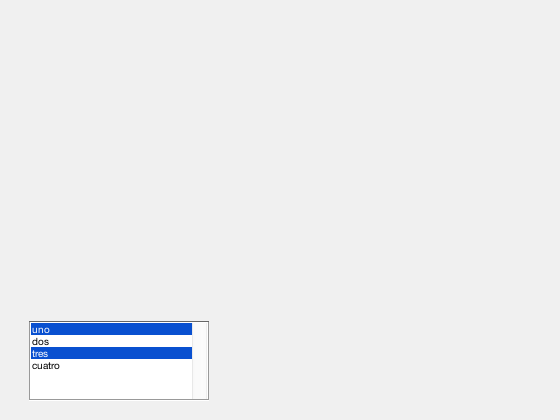

b1 = uicontrol(p, 'Style', 'pushbutton', 'String', 'Botón 1',...
        'Units', 'normalized', 'Position', [.1 .55 .8 .3]);
    
b2 = uicontrol(p, 'Style', 'pushbutton', 'String', 'Botón 2',...

        'Units', 'normalized', 'Position', [.1 .15 .8 .3]);        

## Button groups

El siguiente código crea un grupo de botones. 

f = figure;
bg = uibuttongroup(f, 'Title', 'Mi grupo de botones', ...
    'Position', [.1 .2 .8 .6]);

Se crean dos *radio buttons *con los siguientes comandos:

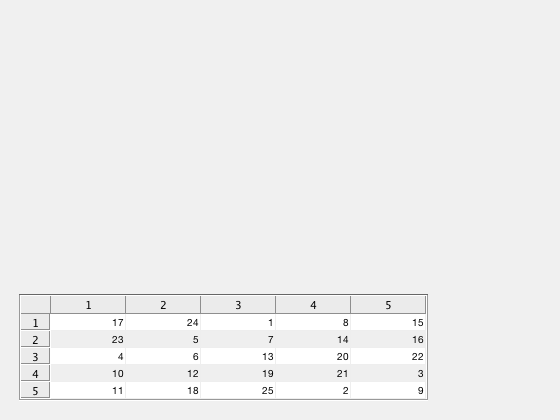

rd1 = uicontrol(bg, 'Style', 'radiobutton', 'String', 'Rojo', ...
    'Units', 'normalized', ...

    'Position', [.1 .6 .3 .2]);
rd2 = uicontrol(bg, 'Style', 'radiobutton', 'String', 'Azul', ...
    'Units', 'normalized', ...
    'Position', [.1 .2 .3 .2]);

Los grupos permiten que sólo un botón de tipo radio o toggle pueda ser seleccionado a la vez.

## Axes

El siguiente código crea ejes en una figura:

f = figure;
ax = axes(f, 'Position', [.15 .15 .7 .7]);

## Ejemplo: diseño sencillo.

Este es el código de una UI simple que contiene un eje y un botón.

% edit miui1
miui1

La función principal *miui1 *llama a la función *conComponentes *que devuelve una estructura que cotiene los handles a cada uno de los componentes de la UI. Crea una figura, ejes y un botón. La función *plotsine *grafica el seno dentro de los ejes. 

# *Escritura de Callbacks*

Los componentes UI tienen ciertas propiedades que pueden asociarse con funciones callback. Cada una de estas propiedades se corresponde con una acción del usuario. Un uicontrol tiene una propiedad llamada Callback; el valor de la misma puede ser un handle a una función, una función anónima o un string que contenga comandos Matlab. 

## ¿Cómo se especifica el valor de la propiedad Callback?

Especificar una función handle

Los handles permiten representar una función en una variable. La función se definde localmente, o puede guardarse en un script diferente. La función debe definir dos parámetros de entrada *hObject* y *callackdata*. 

El siguiente código crea un componente tipo deslizante y especifica su callback a una función handle:

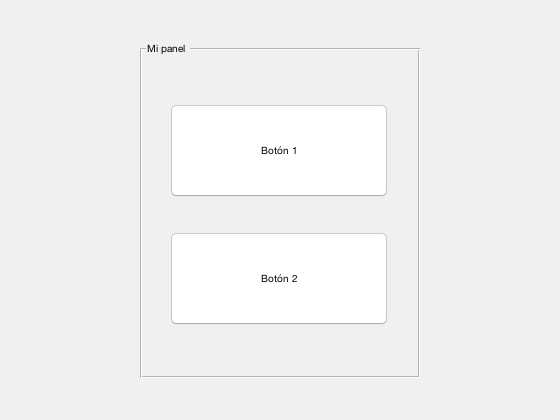

% edit miui2
miui2

La función handle devuelve en el command window el valor del control deslizante una vez que el usuario lo establece en un lugar del canal. 

Especficiar un cell array

Se usan cell arrays para especificar una función callback que acepte argumentos de entrada que uno quiere utilizar en la misma. El primer elemento en el cell array es la función handle, los proximos argumentos son las variables separadas por comas. 

El siguiente ejemplo crea un botón y especifica su callback para que su valor sea un cell array que contiene a la función handle y un argumento de entrada:

% edit miui3
miui3

# App Designer

GUIDE es un entorno de arrastra

Asistente

appdesigner

Un ejemplo:

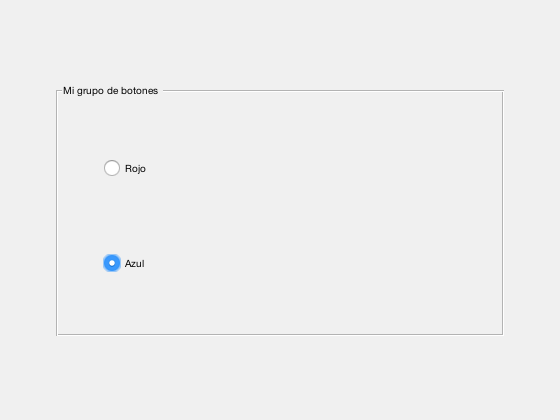

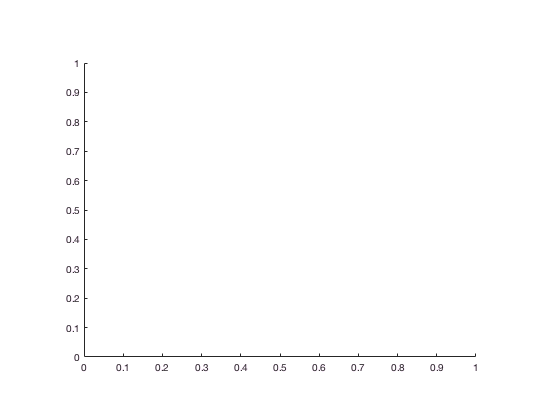

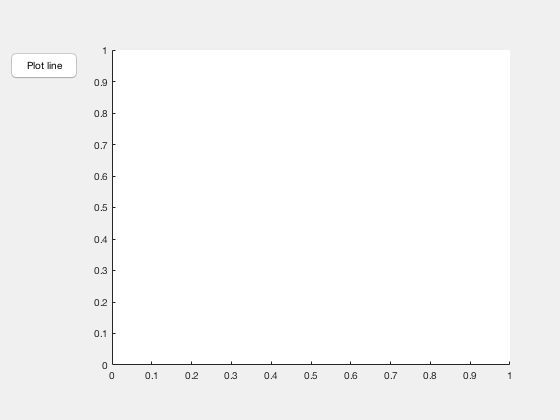

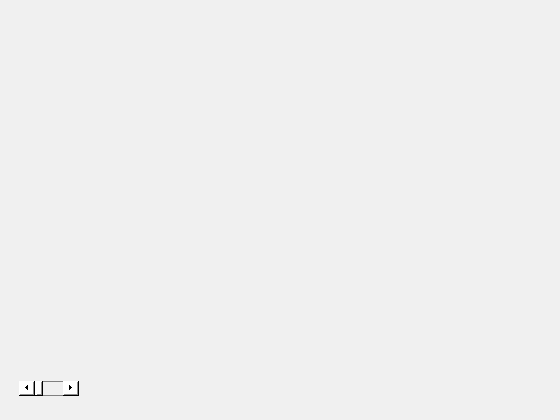

edit appMain.m